# ME 419 Lab 1

**Names:** Julia Fay, Aiden Taylor 

**Date:** 2024.1.11

**Class:** ME419

**Description: **The purpose of this file is to simulate various first and second order mechanical systems using simulink.

## Exercise 1

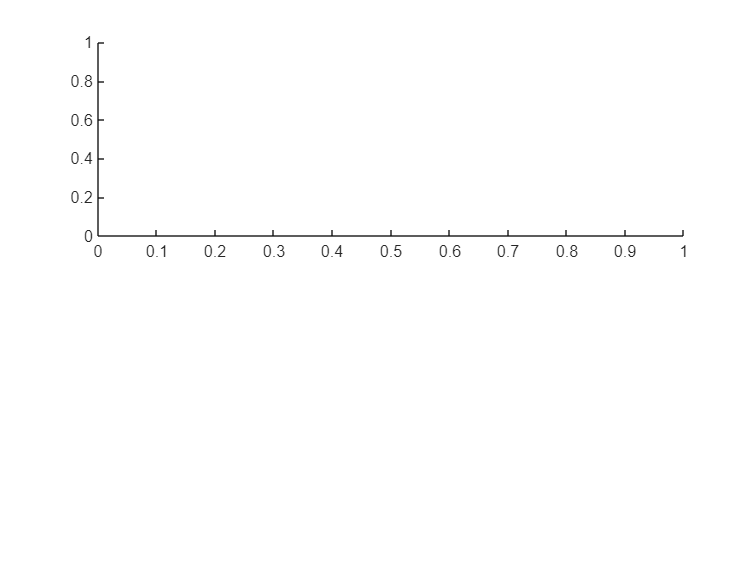

subplot (2,1,1);

x = sim('Lab1_419_simul');  %run simulink simulation

Model 'Lab1_419_simul' was created with a newer version (R2023b) of Simulink
To disable this error message, use Simulink preferences.
To create a model that is compatible with this version of Simulink, load the model in Simulink R2023b and select Save > Export Model to > Previous Version.

plot(x.tout, x.simout(:,1));%plot acceleration
grid on;
title('$\dot{v}$', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Value [m/s^2]')
axis([0 120 -0.2 0.6])
subplot(2,1,2);             %plot velocity
plot(x.tout, x.simout(:,2), '--')
grid on;
title("$\dot{x}$", 'Interpreter', 'latex');
xlabel('Time [s]')
ylabel('Value [m/s]')
axis([0 120 -1 12])
snapshotModel('Lab1_419_simul') %output simulink image

## Exercise 2

%run the block diagram 
run = sim("Lab1_Exercise2_BD.slx");

%import the block diagram image 
snapshotModel('Lab1_Exercise2_BD') 

%create a tiled layout 
fig1 = figure();
tl = tiledlayout(3,1);         
title(tl,'Exercise 2','FontSize',12,'FontWeight','bold');
fig1.Position(3:4) = [560*3 420*5]; %scale subplot

%plot the results for case 1 and format
nexttile; 
plot(run.tout,run.case1)
xlabel("Time [s]");
ylabel("K_s  [in/(gal/min)]");
axis([0 10 -0.1 0.6]);
title('Case 1','FontSize',10,'FontWeight','bold');
grid on

%case 2
%plot the results for case 2 and format
nexttile; 
plot(run.tout,run.case2)
xlabel("Time [s]");
ylabel("K_s  [in/(gal/min)]");
axis([0 10 -1 9]);
title('Case 2','FontSize',10,'FontWeight','bold');
grid on

%case 3
%plot the results for case 3 and format
nexttile;
plot(run.tout,run.case3)
xlabel("Time [s]");
ylabel("K_s  [in/(gal/min)]");
axis([0 100 -0.8 0.1]);
title('Case 3','FontSize',10,'FontWeight','bold');
grid on


## Exercise 3

fig1 = figure();
fig1.Position(3:4) = [560*3 420*5]; %scale subplot
y = sim('Lab1_419_simul3');         %run simulink
subplot (3,1,1);                    %plot sys 1
plot(y.tout, y.simout(:,1));
grid on;
title('Step Response of First System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])

subplot(3,1,2);                     %plot sys 2
plot(y.tout, y.simout1(:,1));
grid on;
title('Step Response of Second System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])

subplot(3,1,3);                     %plot sys 3
plot(y.tout, y.simout2(:,1));
grid on;
title('Step Response of Third System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])
snapshotModel('Lab1_419_simul3')

## Exercise 4

fig1 = figure();
fig1.Position(3:4) = [560*3 420*5]; %scale subplot
z = sim('Lab1_419_simul4');         %run simulink
subplot (2,1,1);                    %plot sys 1
plot(z.tout, z.simout(:,1));
grid on;
title('Step Response of First System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])
subplot (2,1,2);                    %plot sys 1
plot(z.tout, z.simout1(:,1));
grid on;
title('Step Response of Second System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 30 -0.2 2])
snapshotModel('Lab1_419_simul4')